# Lights

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

pl.scene_begin('scene_file', 'lights.pov', 'image_file', 'lights.png');
    pl.include("shapes");
    pl.global_settings("assumed_gamma 1");
    
    % Camera
    pl.camera('angle', 30, 'location', [10 35 6], 'look_at', [0 13 5], 'type', 'perspective');
    
    % Wall
    tex_wall = pl.declare("tex_wall", pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.05 metallic 0.2}"));
    pl.plane('normal', [1,0,0], 'distance', 0, 'texture', tex_wall, 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
   
    % Lights
    rest_comp = 0.42;
    s = 4;
    e = 10;
    n = e - s;
    for y = s:e
        r =  ((y - s) / n);
        pl.sphere('position', [2 y * 1.5 2], 'radius', 0.4, 'texture', 'Yellow_Glass');
        pl.light('location',  [2 y * 1.5 2], 'color', [r rest_comp rest_comp]);
    end

    for y = s:e
        g =  ((y - s) / e);
        pl.sphere('position', [2 y * 1.5 3], 'radius', 0.4, 'texture', 'Dark_Green_Glass');
        pl.light('location',  [2 y * 1.5 3], 'color', [rest_comp g rest_comp]);
    end

    for y = s:e
        g =  ((y - s) / e) * 0.5;
        pl.sphere('position', [2 y * 1.5 4], 'radius', 0.4, 'texture', 'NBwinebottle');
        pl.light('location',  [2 y * 1.5 4], 'color', [rest_comp g rest_comp]);
    end

    for y = s:e
        g =  ((y - s) / e);
        pl.sphere('position', [2 y * 1.5 5], 'radius', 0.4, 'texture', 'NBoldglass');
        pl.light('location',  [2 y * 1.5 5], 'color', [rest_comp g rest_comp]);
    end

    for y = s:e
        r =  ((y - s) / e);
        pl.sphere('position', [2 y * 1.5 6], 'radius', 0.4, 'texture', 'NBglass');
        pl.light('location',  [2 y * 1.5 6], 'color', [r rest_comp rest_comp]);
    end

    for y = s:e
        r =  ((y - s) / e) * 0.6;
        pl.sphere('position', [2 y * 1.5 7], 'radius', 0.4, 'texture', 'Orange_Glass');
        pl.light('location',  [2 y * 1.5 7], 'color', [r rest_comp rest_comp]);
    end

    for y = s:e
        g = ((y - s) / e) * 2.3;
        pl.sphere('position', [2 y * 1.5 8], 'radius', 0.4, 'texture', 'Vicks_Bottle_Glass');
        pl.light('location',  [2 y * 1.5 8], 'color', [ rest_comp g rest_comp]);
    end

pl.scene_end();

#### Render and display

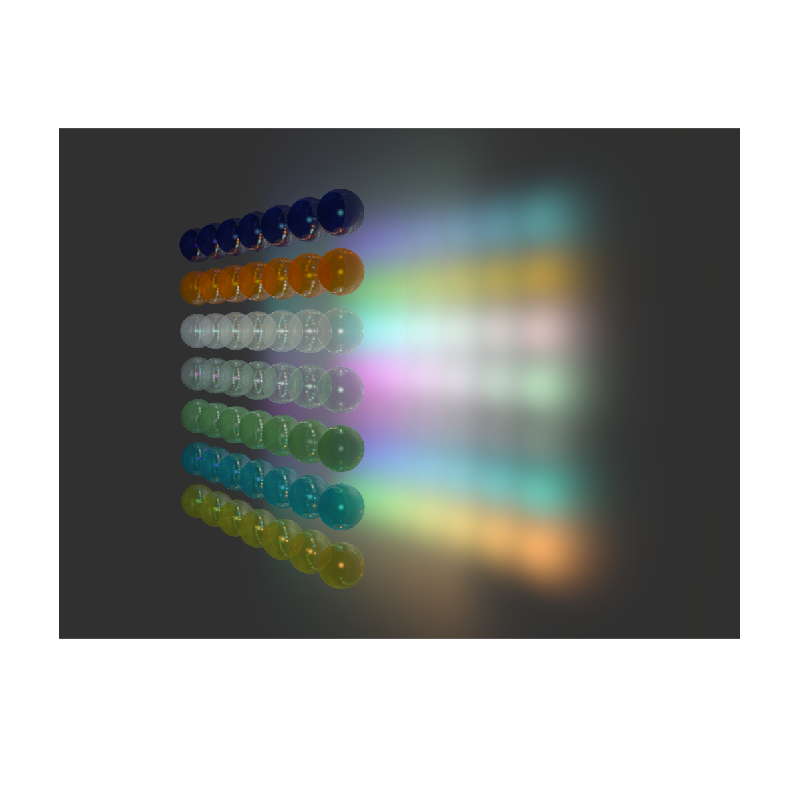

img = pl.render();
imshow(img);

#### Elapsed time

toc

Elapsed time is 187.244172 seconds.
